# Load Raw Data and the Dataset Structure 

load("Workspace_Raw_Data.mat")

# Data Cleaning 

- Remove Rows and columns from Main_Dataset 

- Check for any missing values and remove them.

% Remove rows from 1 to 6 from Main_Dataset and keep the first 8 columns only
for idx = 1:length(dataStruct)
    if isfield(dataStruct(idx), 'Main_Dataset') && ...
       isfield(dataStruct(idx).Main_Dataset, 'data') && ...
       ~isempty(dataStruct(idx).Main_Dataset.data)

        C = dataStruct(idx).Main_Dataset.data;  % Cell array, 1st row = headers

        % Remove rows 1 to 6 and keep only the first 8 columns
        filteredData = C(7:end, 1:8);  % Keep rows from 7 onwards and first 8 columns

        % Convert to table and label the columns
        dataTable = cell2table(filteredData, 'VariableNames', {'Alpha', 'Cl', 'Cd','CDp','Cm','Top Xtr','Bot Xtr','Cpmin'});

        % Store the table back into the struct
        dataStruct(idx).Main_Dataset.data = dataTable;
    end
end

% Check for any missing values and remove them
for idx = 1:length(dataStruct)
    if isfield(dataStruct(idx), 'Main_Dataset') && ...
       isfield(dataStruct(idx).Main_Dataset, 'data') && ...
       ~isempty(dataStruct(idx).Main_Dataset.data)

        dataTable = dataStruct(idx).Main_Dataset.data;  % Table format

        % Remove rows with any missing values
        dataTable = rmmissing(dataTable);

        % Store the cleaned table back into the struct
        dataStruct(idx).Main_Dataset.data = dataTable;
    end
end

# Exploratory Data Analysis 

Other Plots to visualize the features

- Correlation Plot

corr plot

ans =    NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN


% Define variable names for columns 1 to 9
varNames = {'Alpha', 'Cl', 'Cd', 'CDp', 'Cm', 'Top Xtr', 'Bot Xtr', 'Cpmin'};

% Aggregate numeric data from all datasets (columns 1 to 8)
allData = [];
for idx = 1:length(dataStruct)
    if ~isempty(dataStruct(idx).Main_Dataset.data)
        T = dataStruct(idx).Main_Dataset.data;
        T = T(:,1:8); % Restrict to columns 1-8
        numericVars = varfun(@isnumeric, T, 'OutputFormat', 'uniform');
        allData = [allData; T{:, numericVars}];
    end
end

% Compute correlation matrix
R = corr(allData, 'Rows', 'complete');

% Create heatmap with custom axis labels
figure;
h = heatmap(varNames, varNames, R);

% Add title and axis labels
h.Title = 'Combined Correlation Matrix (Columns 1 to 8)';
h.XLabel = 'Variables';
h.YLabel = 'Variables';

# Feature Engineering 

- Add feature Cl/Cd 

- PCA

# Plots 

GUI Plots

- Cl vs Cd, 

- Cl vs Alpha, 

- Cd vs Alpha, 

- Cl & Cd vs Alpha (Superimposed Graph)

- Geometry (X vs Y)

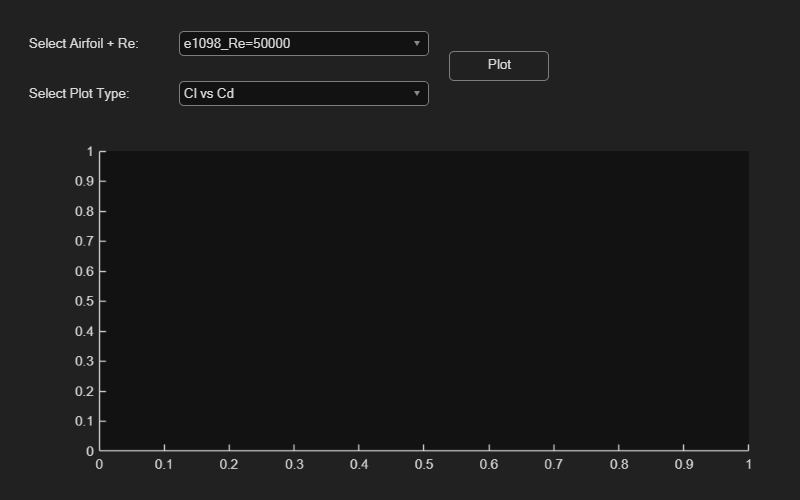

% Calculate Cl/Cd and add to the 9th column for all the files in Main_Dataset
for idx = 1:length(dataStruct)
    if isfield(dataStruct(idx), 'Main_Dataset') && ...
       isfield(dataStruct(idx).Main_Dataset, 'data') && ...
       ~isempty(dataStruct(idx).Main_Dataset.data)

        dataTable = dataStruct(idx).Main_Dataset.data;  % Table format

        % Extract Cl and Cd columns
        Cl = dataTable.Cl;  % Assuming Cl is in the second column
        Cd = dataTable.Cd;  % Assuming Cd is in the third column

        % Calculate Cl/Cd, avoiding division by zero
        ClCd = Cl ./ Cd;
        ClCd(Cd == 0) = NaN;  % Set Cl/Cd to NaN where Cd is zero

        % Add Cl/Cd to the table as a new column
        dataTable.ClCd = ClCd;

        % Store the updated table back into the struct
        dataStruct(idx).Main_Dataset.data = dataTable;
    end
end

% Call the airfoilPlotterGUI function with the cleaned and processed dataStruct
airfoilPlotterGUI(dataStruct)

# Coordinate Geometry Flattening into the MainDataset 

% Flatten Coordinate Geometry into the MainDataset
for i = 1:length(dataStruct)
    entry = dataStruct(i);

    % Skip if missing geometry or main dataset
    if isempty(entry.Coordinate_Geometry.data) || isempty(entry.Main_Dataset.data)
        continue;
    end

    % Geometry: [x y] → flatten into row: [x1, x2, ..., y1, y2, ...]
    geom = entry.Coordinate_Geometry.data;
    x = geom(:, 1)';
    y = geom(:, 2)';
    geom_flat = [x, y];  % 1 row, 2N columns

    % Extract and convert main data
    raw = entry.Main_Dataset.data;
    if iscell(raw)
        % Convert cell to table with headers
        headers = string(raw(1, :));
        dataRows = raw(2:end, :);
        T = cell2table(dataRows, 'VariableNames', headers);
    elseif istable(raw)
        T = raw;
    else
        warning("Unrecognized Main_Dataset format at index %d", i);
        continue;
    end

    % Create geometry table with repeated row to match T
    nRows = height(T);
    geomTable = array2table(repmat(geom_flat, nRows, 1));

    % Create variable names: x1, x2, ..., y1, y2, ...
    nPoints = length(x);
    xVars = "x" + (1:nPoints);
    yVars = "y" + (1:nPoints);
    geomTable.Properties.VariableNames = [xVars, yVars];

    % Insert geometry columns after 4th column (Cl/Cd)
    T = [T(:,1:9), geomTable, T(:,10:end)];

    % Update struct
    dataStruct(i).Main_Dataset.data = T;
end


#  Resample all coordinate geometries to a fixed number of points

targetPoints = 50;  % Desired number of resampled x and y points

for i = 1:numel(dataStruct)
    T = dataStruct(i).Main_Dataset.data;

    % Identify geometry columns
    varNames = string(T.Properties.VariableNames);
    xCols = varNames(startsWith(varNames, 'x'));
    yCols = varNames(startsWith(varNames, 'y'));

    if isempty(xCols) || isempty(yCols)
        warning('Skipping entry %d: No geometry columns found.', i);
        continue;
    end

    xVals = T{:, xCols};
    yVals = T{:, yCols};

    xNew_all = zeros(height(T), targetPoints);
    yNew_all = zeros(height(T), targetPoints);

    for r = 1:height(T)
        x = xVals(r, :);
        y = yVals(r, :);

        % Remove NaNs
        valid = ~isnan(x) & ~isnan(y);
        x = x(valid);
        y = y(valid);

        if length(x) < 2
            warning('Row %d has insufficient geometry points. Skipping.', r);
            continue;
        end

        % Compute arc length
        s = [0, cumsum(sqrt(diff(x).^2 + diff(y).^2))];
        s = s / max(s);  % Normalize to [0, 1]

        % Remove duplicate s values
        [sUnique, ia] = unique(s);
        x = x(ia);
        y = y(ia);

        % Interpolate
        sNew = linspace(0, 1, targetPoints);
        xNew = interp1(sUnique, x, sNew, 'linear', 'extrap');
        yNew = interp1(sUnique, y, sNew, 'linear', 'extrap');

        xNew_all(r, :) = xNew;
        yNew_all(r, :) = yNew;
    end

    % Create column names
    xNewNames = compose("x%03d", 1:targetPoints);
    yNewNames = compose("y%03d", 1:targetPoints);

    geomTable = array2table([xNew_all, yNew_all], 'VariableNames', [xNewNames, yNewNames]);

    % Remove old geometry
    T(:, [xCols, yCols]) = [];

    % Add resampled geometry
    dataStruct(i).Main_Dataset.data = [T geomTable];
end

# All Struct Combination to one Table

% Initialize final table
Training_Data_Table = table();

% Loop through all entries
for i = 1:numel(dataStruct)
    entry = dataStruct(i);

    % Skip if Main_Dataset is missing
    if isempty(entry.Main_Dataset.data)
        continue;
    end

    % Get the table
    T = entry.Main_Dataset.data;

    % Add identifier columns
    T.Airfoil = repmat(string(entry.Airfoil), height(T), 1);
    T.Re = repmat(entry.Reynolds, height(T), 1);

    % Reorder columns: Airfoil | Re | ...
    T = movevars(T, {'Airfoil', 'Re'}, 'Before', 1);

    % Append to main table
    Training_Data_Table = [Training_Data_Table; T];
end

# Principle Compoonent Analysis

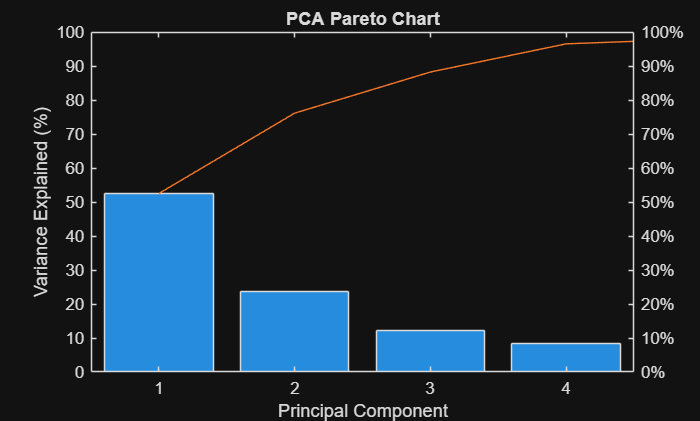

% Remove rows with any NaN or Inf values (important!)
allData = allData(all(all(isfinite(allData),2), 2), :);

% Remove constant columns
variances = var(allData);
constantCols = variances == 0;
allData(:, constantCols) = [];
varNamesCleaned = varNames(~constantCols);  % update variable names

% Standardize (zero mean, unit variance)
allData_norm = zscore(allData);

% Apply PCA
[coeff, score, latent, tsquared, explained] = pca(allData_norm);

% Pareto chart of explained variance
figure;
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained (%)')
title('PCA Pareto Chart')

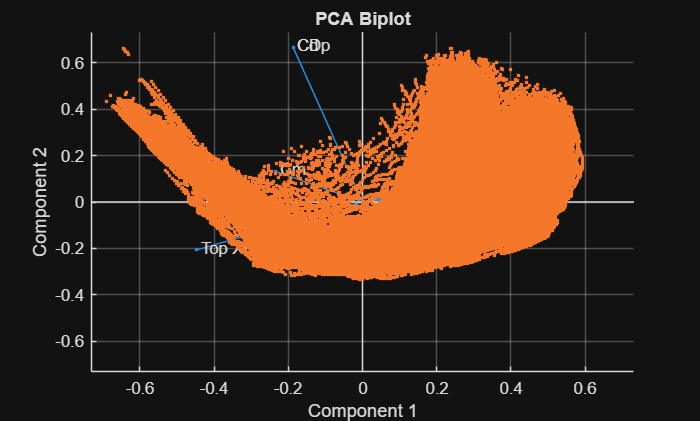


% Optional: biplot to visualize loadings
figure;
biplot(coeff(:,1:2), 'Scores', score(:,1:2), 'VarLabels', varNamesCleaned)
title('PCA Biplot')
grid on


% Show explained variance
disp('Explained Variance (%):')

Explained Variance (%):


disp(explained)

   52.5095
   23.6261
   12.0924
    8.2862
    1.4919
    1.3133
    0.6789
    0.0017



disp('Cumulative Explained Variance (%):')

Cumulative Explained Variance (%):


disp(cumsum(explained))

   52.5095
   76.1355
   88.2279
   96.5141
   98.0060
   99.3193
   99.9983
  100.0000



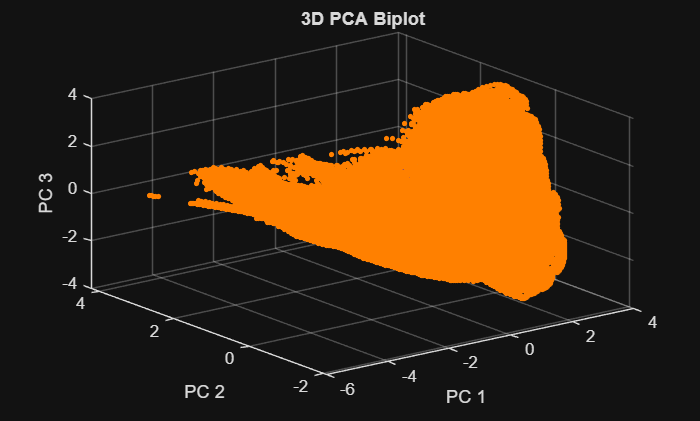


% 3D BIPLOT PART

figure
scatter3(score(:,1), score(:,2), score(:,3), 10, 'filled', 'MarkerFaceColor',[1 0.5 0]) % orange RGB
xlabel('PC 1')
ylabel('PC 2')
zlabel('PC 3')
title('3D PCA Biplot')
grid on
hold on

% Plot the variable loadings as arrows
scale = 3; % adjust for visibility
for i = 1:size(coeff,1)
    quiver3(0, 0, 0, scale*coeff(i,1), scale*coeff(i,2), scale*coeff(i,3), 'LineWidth', 2, 'Color', 'b')
    text(scale*coeff(i,1), scale*coeff(i,2), scale*coeff(i,3), varNamesCleaned{i}, 'FontSize', 12, 'Color', 'cyan')
end
hold off

# Extracts the predictors and responses from `Training_Data_Table`

% Extract predictor variables: Re, Alpha, Cl, Cd, Cdp
Predictor_Var = Training_Data_Table{:, {'Alpha', 'Cl', 'Cd','CDp','ClCd'}};

% Extract response variables: Flattened coordinate geometry (columns 7 onward)
geometryVarNames = Training_Data_Table.Properties.VariableNames(12:end);
Response_Var = Training_Data_Table{:, geometryVarNames};

% Save to file for reuse
save('NN_Training_Data.mat', 'Predictor_Var', 'Response_Var');